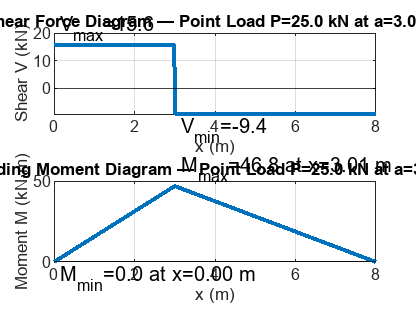

%% Shear Force & Bending Moment Diagrams for a Simply Supported Beam

%% Beam geometry
L = 8;            % span (m)

%% Choose load case
load_case = 'point';   % 'point' or 'udl'

switch lower(load_case)
    case 'point'
        P = 25e3;      % point load (N)
        a = 3.0;       % distance from left support A (m), 0 < a < L

        % Reactions
        RA = P*(L-a)/L;
        RB = P*a/L;

        % Discretize and compute V, M
        x = linspace(0,L,400);
        V = RA * ones(size(x));
        M = RA .* x;
        idx = x >= a;
        V(idx) = V(idx) - P;
        M(idx) = M(idx) - P .* (x(idx) - a);

        case_title = sprintf('Point Load P=%.1f kN at a=%.2f m', P/1e3, a);

    case 'udl'
        w = 6e3;       % uniform load (N/m)

        % Reactions
        RA = w*L/2;
        RB = w*L/2;

        % Discretize and compute V, M (for full-length UDL)
        x = linspace(0,L,400);
        V = RA - w.*x;
        M = RA.*x - 0.5*w.*x.^2;

        case_title = sprintf('UDL w=%.1f kN/m over full span', w/1e3);

    otherwise
        error('Unknown load_case. Use ''point'' or ''udl''.');
end

%% Max/min values
[ Mmax, iM ] = max(M); [ Mmin, jM ] = min(M);
[ Vmax, iV ] = max(V); [ Vmin, jV ] = min(V);

%% Plot SFD & BMD
figure;

subplot(2,1,1);
plot(x, V/1e3, 'LineWidth', 2); grid on; box on;
yline(0,'k-');
xlabel('x (m)'); ylabel('Shear V (kN)');
title(['Shear Force Diagram — ', case_title]);

% annotate
text(x(iV), Vmax/1e3, sprintf(' V_{max}=%.1f', Vmax/1e3), ...
    'VerticalAlignment','bottom','HorizontalAlignment','left');
text(x(jV), Vmin/1e3, sprintf(' V_{min}=%.1f', Vmin/1e3), ...
    'VerticalAlignment','top','HorizontalAlignment','left');

subplot(2,1,2);
plot(x, M/1e3, 'LineWidth', 2); grid on; box on;
yline(0,'k-');
xlabel('x (m)'); ylabel('Moment M (kN·m)');
title(['Bending Moment Diagram — ', case_title]);

% annotate
text(x(iM), Mmax/1e3, sprintf(' M_{max}=%.1f at x=%.2f m', Mmax/1e3, x(iM)), ...
    'VerticalAlignment','bottom','HorizontalAlignment','left');
text(x(jM), Mmin/1e3, sprintf(' M_{min}=%.1f at x=%.2f m', Mmin/1e3, x(jM)), ...
    'VerticalAlignment','top','HorizontalAlignment','left');


%% Console summary
fprintf('Reactions:  RA = %.1f kN,  RB = %.1f kN\n', RA/1e3, RB/1e3);

Reactions:  RA = 15.6 kN,  RB = 9.4 kN


fprintf('Max Shear:  Vmax = %.1f kN,  Vmin = %.1f kN\n', Vmax/1e3, Vmin/1e3);

Max Shear:  Vmax = 15.6 kN,  Vmin = -9.4 kN


fprintf('Max Moment: Mmax = %.1f kN·m at x = %.2f m\n', Mmax/1e3, x(iM));

Max Moment: Mmax = 46.8 kN·m at x = 3.01 m


if Mmin < 0
    fprintf('Min Moment: Mmin = %.1f kN·m at x = %.2f m\n', Mmin/1e3, x(jM));
end
